# AOI_Lab : BardcodeRead

#### Fred liu 2023.07.12

使用readBarcode的指令可以辨識一維與二維的條碼



I = imread("code03.jpg");
[msg, ~, loc] = readBarcode(I);

% Annotate the image with the decoded message.
xyText =  loc(2,:);
Imsg = insertText(I, xyText, msg, "BoxOpacity", 1, "FontSize", 25);
disp(msg)

https://medium.com/@FredLiu_


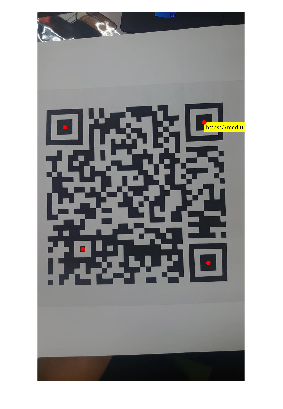

% Insert filled circles at the finder pattern locations.
Imsg = insertShape(Imsg, "FilledCircle", [loc, ...
    repmat(10, length(loc), 1)], "Color", "red", "Opacity", 1);

% Display image.
imshow(Imsg)